cd /Users/murph/Documents/Github/GFI_onManifolds/HMC_onSphere/
n = 20;
shift_vector=[0;0;1];
m1 = -sqrt(5/8) + shift_vector(1);
m2 = 1/sqrt(8) + shift_vector(2);
m3 = 1/sqrt(16) + shift_vector(3);
sd1 = 1;
sd2 = 1;
sd3 = 1;
rng(13);
DataX = normrnd(m1,sd1,[n,1]);
DataY = normrnd(m2,sd2,[n,1]);
DataZ = normrnd(m3,sd3,[n,1]);

Using the above data, we'll try to integrate numerically using the parameterized version in sphereical coordinates, the non-parameterized version in sphereical coordinates, and the non-parameterized version in cartesian coordinates. This implementation using the Jacobian method found in the L2wConstraint_v3.pdf file. Uses the L2 norm and the implicit function theorem.

We will now sample from the CHMC:

% Arbitrarily choosing the starting value:
q0=[1/sqrt(4)+shift_vector(1);1/sqrt(4)+shift_vector(2);(1/sqrt(2)+shift_vector(3))]

q0 =     0.5000
    0.5000
    1.7071


nllFunc = @(x) nll_density(x,sd1,sd2,sd3,DataX,DataY,DataZ,shift_vector);
conFunc = @(x) sphereConstraint(x,shift_vector);

% Set parameters (that I don't quite understand)
nRuns = 1+10;
Nscale = 2000000;
runTime = 15; % Time per run in seconds
nTrials = 1;
doPrint = false;

samplers = struct([]);

h = .15;
M = 1;
L = 1;
hmcOpts = struct('intMethod',0,'doPrint',doPrint,'printMod',10);
samplers(end+1).name = sprintf('CHMC (L = %d)',L);
samplers(end).desc = sprintf('M = %g, h = %g',M,h);
samplers(end).func = @(q,N) constrainedHMC(q,nllFunc,conFunc,M,N,L,h,hmcOpts);
samplers(end).N = ceil(Nscale./L);
samplers(end).style = 'b-';

samplerQs = cell(length(samplers),1+nTrials);
samplerStats = cell(length(samplers),1+nTrials);
samplerNLLs = cell(length(samplers),1+nTrials);
samplerTs = zeros(length(samplers),1+nTrials);
for i = 1:numel(samplers)
    fprintf('%s...',samplers(i).name);
    [q1,qs,samplerStats{i,1}] = samplers(i).func(q0,samplers(i).N);
    samplerQs{i,1} = [q0 qs q1];
    samplerTs(i,1) = samplerStats{i,1}.t/samplerStats{i,1}.N;
    samplerNLLs{i,1} = nllFunc(samplerQs{i,1});
    
    currN = ceil(runTime./samplerTs(i,1));
    fprintf('%d samples: ',currN);
    fprintf('\n');
end

CHMC (L = 1)...

20508 samples: 

mean(samplerStats{1,1}.accepted)

ans = 0.3637

Qs = samplerQs{1,1};
% save("HMC_sphereDraws.mat",'Qs');

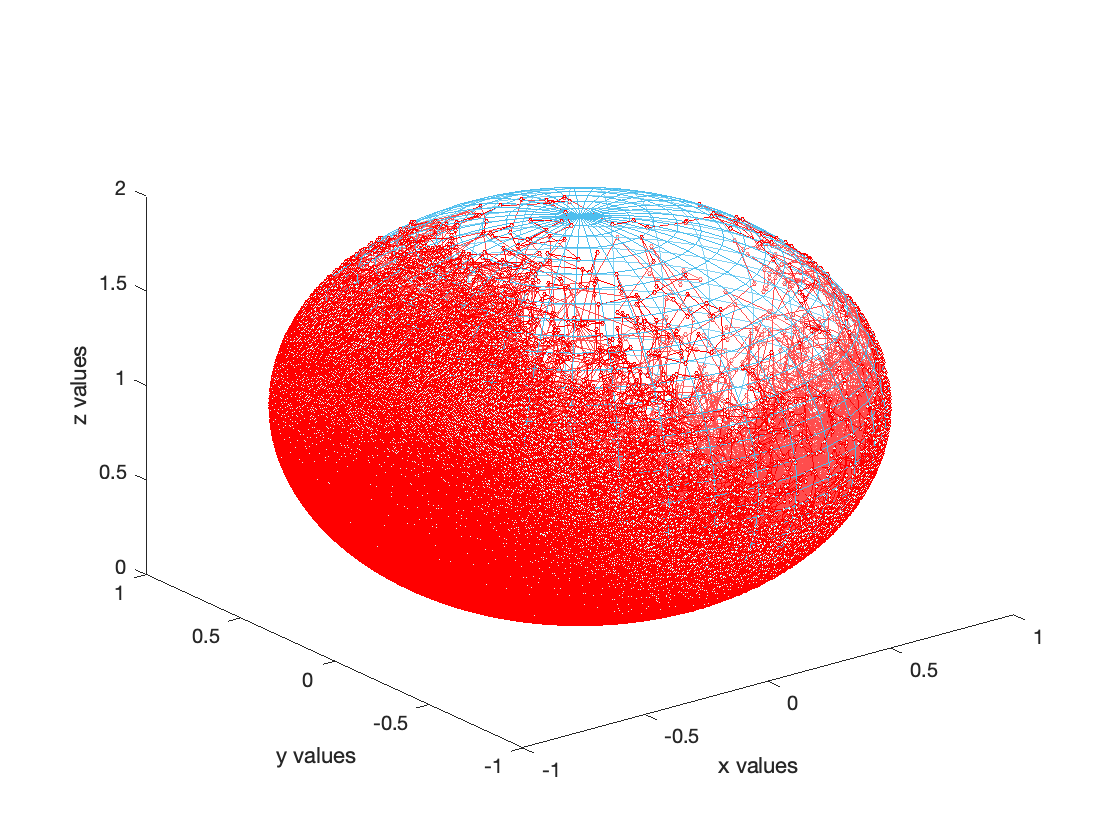

% Qs=load("HMC_sphereDraws.mat");
% xs=real(Qs.Qs(1,:))';
% ys=real(Qs.Qs(2,:))';
% zs=real(Qs.Qs(3,:))';
xs=real(Qs(1,:))';
ys=real(Qs(2,:))';
zs=real(Qs(3,:))';
dim=size(xs);
burnout=floor(dim(1)/2);
xs_burnout=xs(burnout:dim(1),1); 
ys_burnout=ys(burnout:dim(1),1);
zs_burnout=zs(burnout:dim(1),1);
newdim=size(xs_burnout);
walk_surface=plot3(xs_burnout,ys_burnout,zs_burnout,'-o','Color','r','MarkerSize',2,'MarkerFaceColor','#D9FFFF');
hold on
theta=linspace(0,2*pi,40);
phi=linspace(0,pi,40);
[theta,phi]=meshgrid(theta,phi);
rho=1;
x=rho*(sin(phi).*cos(theta)+shift_vector(1));
y=rho*(sin(phi).*sin(theta)+shift_vector(2));
z=rho*(cos(phi)+shift_vector(3));
mesh_surface=mesh(x,y,z,'EdgeColor',[0.3010 0.7450 0.9330],'FaceAlpha',.3);
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
hold off

I thought it might also be interesting to normalize our density and plot it:

## Heatmap using CHMC

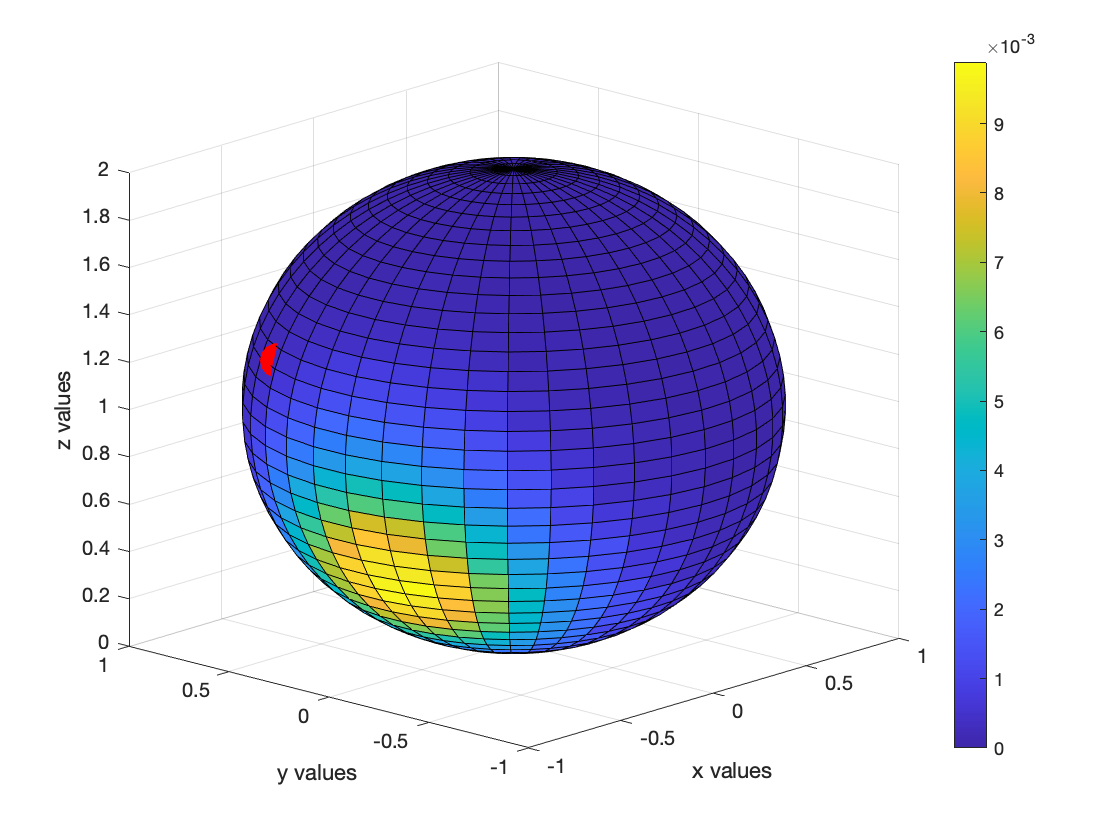

thetas_burnout_unshifted=atan((ys_burnout-shift_vector(2))./...
    (xs_burnout-shift_vector(1)));
thetas_burnout=thetas_burnout_unshifted+pi*((xs_burnout-shift_vector(1))<0)+...
    2*pi*((xs_burnout-shift_vector(1))>0&(ys_burnout-shift_vector(2))<0);
thetas_burnout(isnan(thetas_burnout))=0;
phis_burnout=acos(zs_burnout-shift_vector(3));

[n,d]=size(theta);
theta=linspace(0,2*pi,40);
phi=linspace(0,pi,40);
[theta,phi]=meshgrid(theta,phi);
rho=1;
x=rho*(sin(phi).*cos(theta)+shift_vector(1));
y=rho*(sin(phi).*sin(theta)+shift_vector(2));
z=rho*(cos(phi)+shift_vector(3));
dens_sphere=zeros(n,d);
for t=1:(n-1)
    for p=1:(d-1)
        x_in= (thetas_burnout>=theta(p,t))&(thetas_burnout<theta(p,t+1));
        y_in= (phis_burnout>=phi(p,t))&(phis_burnout<phi(p+1,t));
        dens_sphere(p,t)=mean(x_in&y_in);
    end
end

s2=surf(x,y,z);
s2.CData=dens_sphere;
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
colorbar
view([-47.19 17.56])
% set(h, 'ylim', [0 0.45])
hold on
plot3(m1-0.05,m2+0.05,m3+0.05,'.','Color','r','MarkerSize',60)
hold off

## Heatmap using our explicit density

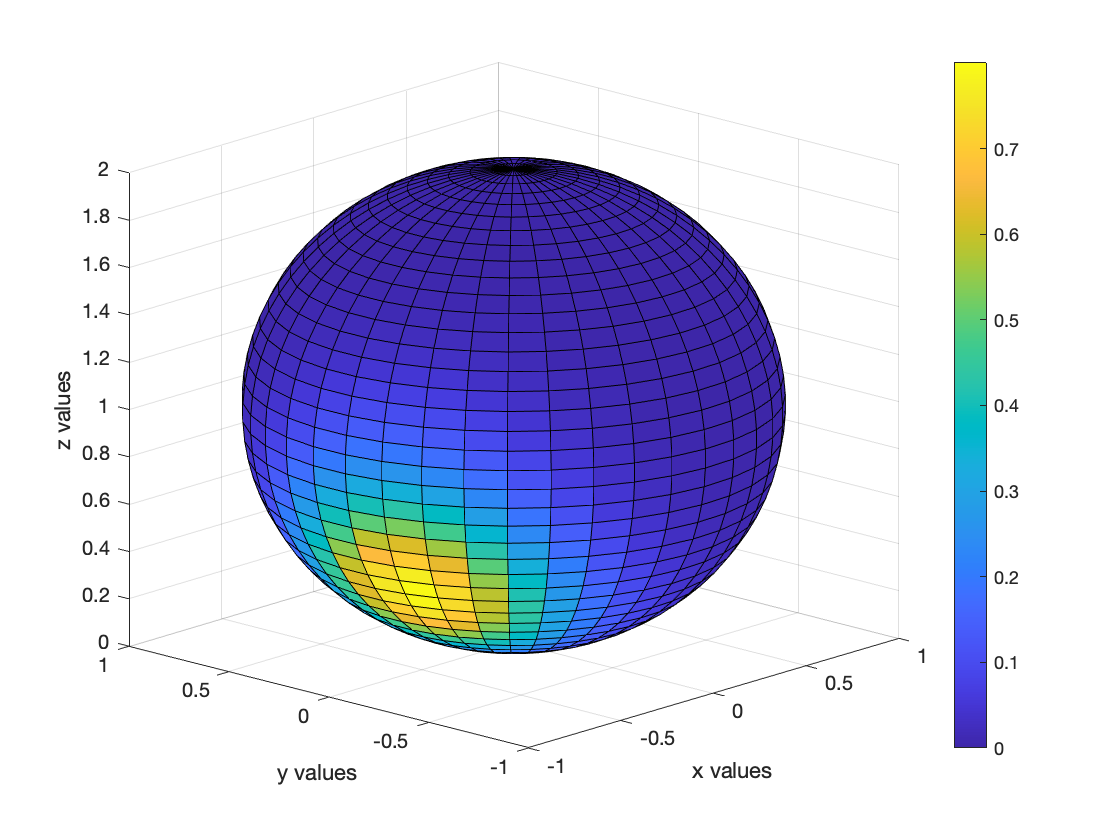

% Get the total probability mass:
fun2 = @(p,t) full_density_spherical(p,...
    t,sd1,sd2,sd3,DataX,DataY,DataZ,shift_vector);
unparameterized_integral = integral2(fun2,0,pi,0,2*pi);

% Get the density of every section:
theta=linspace(0,2*pi,40);
phi=linspace(0,pi,40);
[theta,phi]=meshgrid(theta,phi);
rho=1;
x=rho*(sin(phi).*cos(theta)+shift_vector(1));
y=rho*(sin(phi).*sin(theta)+shift_vector(2));
z=rho*(cos(phi)+shift_vector(3));
dens=full_density_spherical(phi,...
    theta,sd1,sd2,sd3,DataX,...
    DataY,DataZ,shift_vector)/unparameterized_integral;
dens(isnan(dens))=0;
s=surf(x,y,z);
s.CData =dens;
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
colorbar
view([-47.19 17.56])

% set(h, 'ylim', [0 0.45])
% hold on
% % plot3(m1-0.05,m2+0.05,m3+0.05,'.','Color','r','MarkerSize',60)
% hold off

## Heap map using parameterized density (no projection)

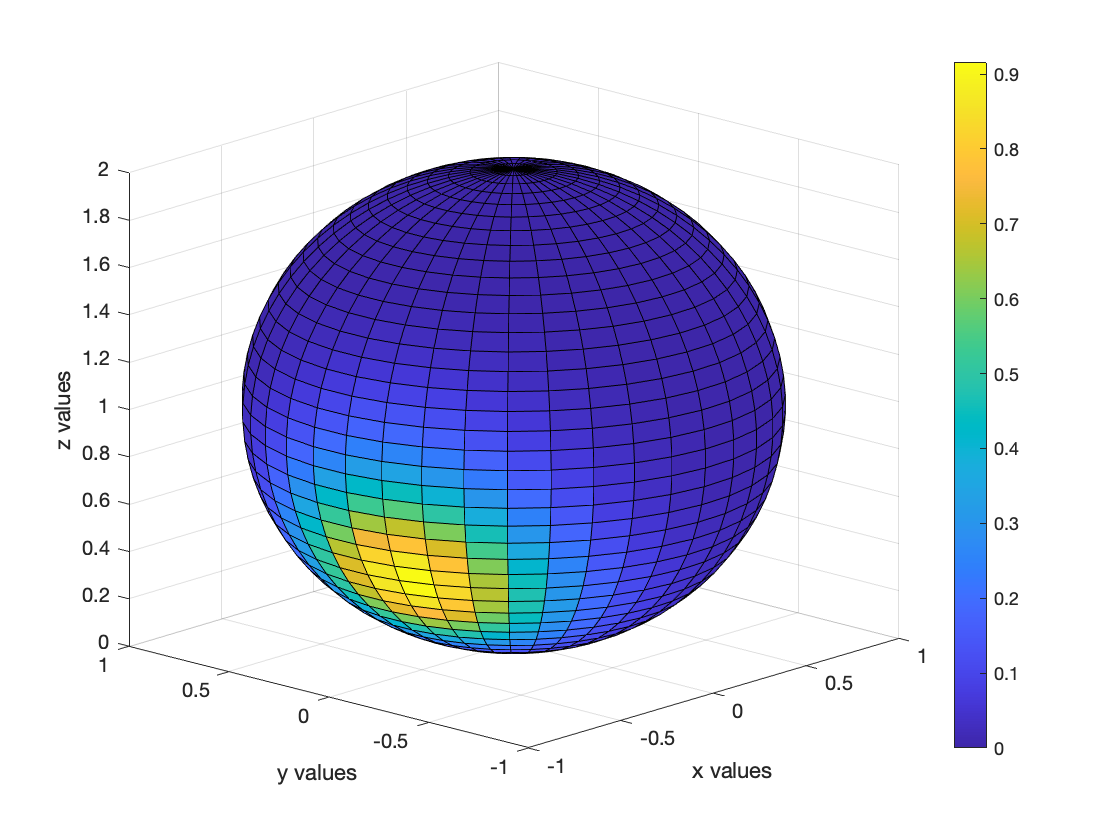

% Get the total probability mass:
fun2 = @(p,t) full_density_spherical_parameterized(p,...
    t,sd1,sd2,sd3,DataX,DataY,DataZ,shift_vector);
unparameterized_integral = integral2(fun2,0,pi,0,2*pi);

% Get the density of every section:
theta=linspace(0,2*pi,40);
phi=linspace(0,pi,40);
[theta,phi]=meshgrid(theta,phi);
rho=1;
x=rho*(sin(phi).*cos(theta)+shift_vector(1));
y=rho*(sin(phi).*sin(theta)+shift_vector(2));
z=rho*(cos(phi)+shift_vector(3));
dens=full_density_spherical_parameterized(phi,...
    theta,sd1,sd2,sd3,DataX,...
    DataY,DataZ, shift_vector)/unparameterized_integral;
dens(isnan(dens))=0;
s=surf(x,y,z);
s.CData=dens;
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
colorbar
view([-47.19 17.56])

% set(h, 'ylim', [0 0.45])
% hold on
% plot3(m1-0.05,m2+0.05,m3+0.05,'.','Color','r','MarkerSize',60)
% hold off

## Integrating over both spaces

Suppose we want to find the area of the first positive octant of a sphere (0<=phi<=pi/2, 0<=theta<=pi/2).

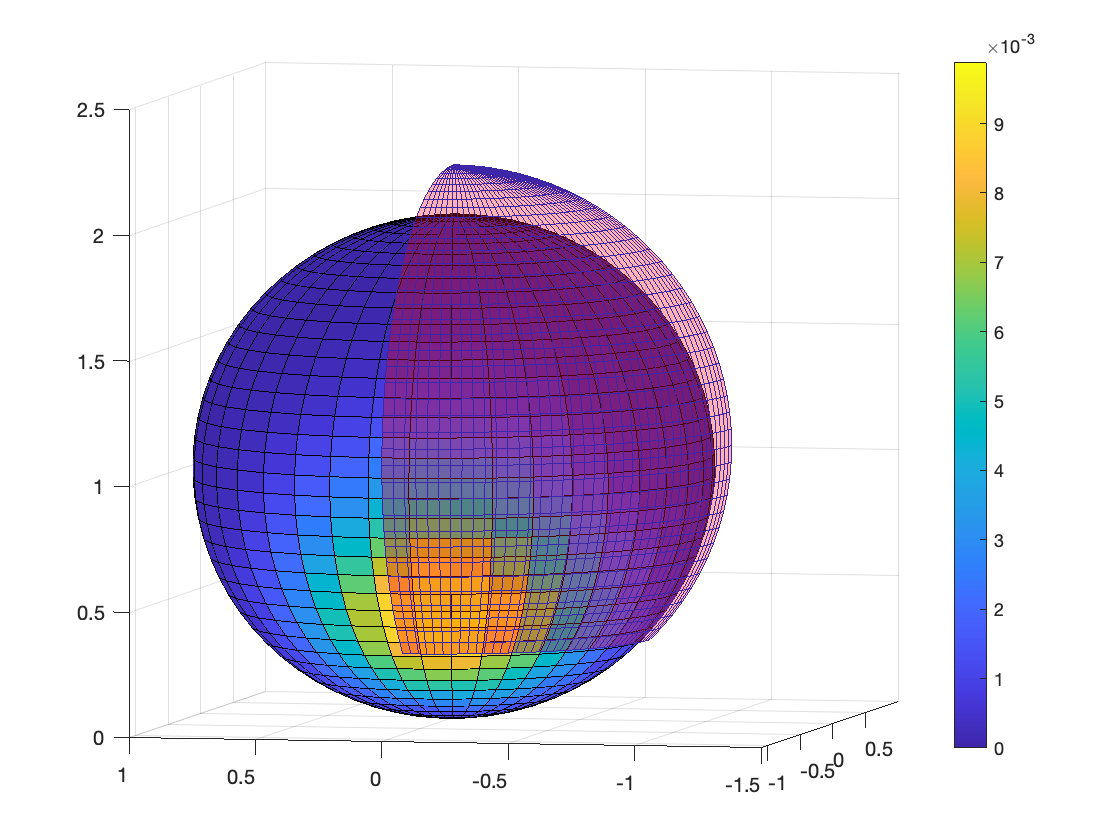

%%%% This would include the following section of the sphere:
% Parameters
theta_sec=linspace(pi,3*pi/2,40);
phi_sec=linspace(0,3*pi/4,40);
[theta_sec,phi_sec]=meshgrid(theta_sec,phi_sec);
rho=1.1;
x_sec=rho*(sin(phi_sec).*cos(theta_sec)+shift_vector(1));
y_sec=rho*(sin(phi_sec).*sin(theta_sec)+shift_vector(2));
z_sec=rho*(cos(phi_sec)+shift_vector(3));

% Plots
surf(x,y,z,dens_sphere)
colorbar
hold on
mesh(x_sec,y_sec,z_sec,zeros(40,40),'FaceColor','r','FaceAlpha',.3)
hold off


%%%%%%%%%%%%% Explicit Integral
fun2 = @(p,t) full_density_spherical(p,...
    t,sd1,sd2,sd3,DataX,DataY,DataZ,shift_vector);
unparameterized_integral = integral2(fun2,0,pi,0,2*pi);
unparameterized_section = integral2(fun2,0,3*pi/4,pi,3*pi/2);

%%%%%%%%%%%%% Proportion of HMC
[n,d]=size(theta_sec);
integral_value=0;
for t=2:n
    for p=2:d
        x_in= (thetas_burnout>=theta_sec(p,t-1))&(thetas_burnout<theta_sec(p,t));
        y_in= (phis_burnout>=phi_sec(p-1,t))&(phis_burnout<phi_sec(p,t));
        integral_value=integral_value+mean(x_in&y_in);
    end
end

unparameterized_section/unparameterized_integral

ans = 0.4484

integral_value

integral_value = 0.4440

## Hamiltonian MC with Constraint Parameterized

% % General sphere parameters
% STANdata=readmatrix("sphereDraws.csv");
% theta=linspace(0,2*pi,40);
% phi=linspace(0,pi,40);
% [theta,phi]=meshgrid(theta,phi);
% rho=1;
% x=rho*(sin(phi).*cos(theta)+shift_vector(1));
% y=rho*(sin(phi).*sin(theta)+shift_vector(2));
% z=rho*(cos(phi)+shift_vector(3));
% 
% % Our HMC draws from theta,phi
% phis_burnout=STANdata(:,2); 
% thetas_burnout=STANdata(:,3);
% 
% [n,d]=size(theta);
% dens2=zeros(n,d);
% for t=2:n
%     for p=2:d
%         x_in= (thetas_burnout>=theta(p,t-1))&(thetas_burnout<theta(p,t));
%         y_in= (phis_burnout>=phi(p-1,t))&(phis_burnout<phi(p,t));
%         dens2(p,t)=mean(x_in&y_in); %*...
% %             sin(phi(p,t));
%     end
% end
% s2=surf(x,y,z);
% n=size(thetas_burnout,1);
% s2.CData=dens2/n;
% xlabel('x values') 
% ylabel('y values')
% zlabel('z values') 
% colorbar
% hold on
% plot3(m1-0.05,m2+0.05,m3+0.05,'.','Color','r','MarkerSize',60)
% hold off
% 
% save("sphereData.mat")